# LECTURE WEEK V. - HANDS-ON

# DISCRETE-TIME FOURIER TRANSFORM AND DISCRETE FOURIER TRANSFORM

**Objectives:**

- Computing the DTFT and DFT of a discrete-time signal.

- Relate the discrete-­time Fourier Transform (DTFT) to the practical Discrete Fourier Transform (DFT).

- Understanding and interpretation of DFT results and spectra computed by using DFTs.

- Creating signals in the DFT domain.

- Estimation of the frequency of a harmonic component (cosine) in a signal.

## MATLAB HANDS-ON Assignment V.1: Phase of the spectrum

**Completion requirements:**

- Explain the similarities and differences between your plots from assignments ***A*** and ***C*** and the referred plots of the class lecture.

- Explain how you verified complex conjugate symmetry in assignment ***B***.

- Explain your choice of $y[0]$ in assignment ***D***, and similarities and differences from your plots in assignment ***D*** in comparison to the earlier plots.

- Show and explain the effects of two other delay intervals as requested in assignment ***E***.

- Show and explain the effects of left-shifting $x[0]$ as requested in assignment ***F***.

In MATLAB Exercise ***V.3****,* we considered the *magnitude* of the spectrum. In this assignment, we look more closely at the *phase* of the spectrum. We study the DFT of the signal $x[n] = d[n] + d[n -1] + d[n - 2]$ and variations of the signal. Make sure to plot digital frequencies on the horizontal axis rather than index numbers of the DFT coefficients.

***A.***

Generate the above signal $x[n]$ in a vector of length 128 and plot $x[n]$. 

***Answer:***

Compute the DFT, and plot the magnitude of the spectrum using a stem plot. 

***Answer:***

Compare this result with the magnitude of the DTFT computed in class room lecture, of which we reproduce the result here.

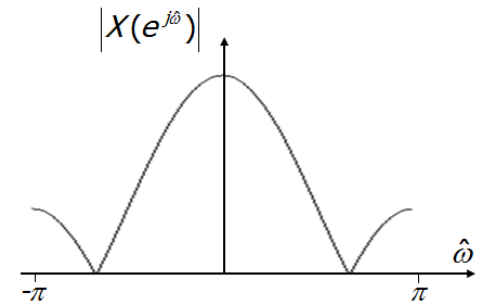

***Answer:***

***B.***

Verify the result of MATLAB Exercise ***V.3 D***, namely complex conjugated symmetry of the DFT coefficients for $\hat{\omega} > \pi$ relative to the DFT coefficients for $\hat{\omega} < \pi$. As an example, verify that the 30-th DFT coefficient, corresponding to digital frequency $\hat{\omega} = (30 - 1)\frac{2\pi}{N} = \frac{58}{128}\pi\approx 1.4235$, is the complex conjugated of the 100-th DFT coefficient, corresponding to $\hat{\omega} = (100 - 1)\frac{2\pi}{N} = \frac{198}{128}\pi \approx 4.8597 = \underbrace{-1.4235}_{symmetry} + \underbrace{2\pi}_{periodicity}$

***Answer:***

***C.***

Now compute the phase of the spectrum using the MATLAB function `angle()``*`. Plot the phase using a stem plot. 

** You may want to try the MATLAB function *`phase()` *and reflect on the difference. Remember, the phase is periodic over *$2\pi$*, which can lead to different phase plots that are actually the same.*

***Answer:***

Compare this result with the phase of the DTFT computed in class room lecture, of which we reproduce the result here.

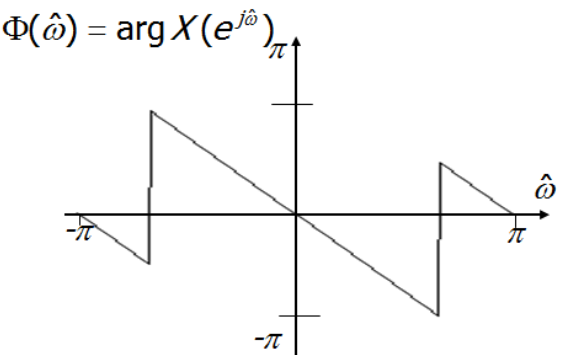

***Answer:***

***D.***

We delay the signal $x[n]$ over one time instance, i.e. right shift the data in the MATLAB vector:


$$y[n] = \delta[n-1] * x[n] = x[n-1]$$


Create the signal $y[n]$ in a vector of length 128. 

***Answer:***

What value did you use for $y[0]$ and why? 

***Answer:***

Compute the DFT (spectrum) of $y[n]$, and plot the magnitude and phase of the spectrum. 

***Answer:***

What do you observe?

***Answer:***

***E.***

What happens to the phase and magnitude of the spectrum when we delay $x[n]$ over even more time instances (try and show at least two different cases)?

***Answer:***

Rather than delaying the phase over a positive number of time instances (i.e. right shift), we can also delay the signal over a negative number of time instance, i.e. left shift the vector. For the signal studied in this assignment, we obtain:

$y[n] = \delta[n+1] * x[n] = x[n+1] = \delta[n+1] + \delta[n] + \delta[n-1]$.

For an infinite-length signal – and hence DTFT – this formulation is perfectly fine, but when working with finite length signals in vectors, the question is where to left-shift the first entry in the vector created in part*** A*** of this assignment. In terms of the above equation, what to do with the signal value $d[n +1]$?

Since effectively the DFT is not only periodic in the frequency domain, but also periodic in the time domain, the answer to this question is that the left most value $x[0]$ shifts to the end of the vector that represents $x[n]$, i.e. to position 128. One can easily visualize this by connecting copies of $x[n]$ to its head and tail, and repeating this process. This process of periodic extension, i.e. circularly connecting head and tail of a finite length signal, is always used in combination with DFTs.

***F.***

Delay the signal $x[n]$ over -1 time instance, effectively left-shifting the signal values by one position. Compute the DFT of $y[n]$, and plot the magnitude and phase of the spectrum using stem plots. 

***Answer:***

What do you observe?

***Answer:***

**Completion requirements:**

- Explain the similarities and differences between your plots from assignments ***A*** and ***C*** and the referred plots of the class lecture.

- Explain how you verified complex conjugate symmetry in assignment ***B***.

- Explain your choice of $y[0]$ in assignment ***D***, and similarities and differences from your plots in assignment ***D*** in comparison to the earlier plots.

- Show and explain the effects of two other delay intervals as requested in assignment ***E***.

- Show and explain the effects of left-shifting $x[0]$ as requested in assignment ***F***.

## MATLAB HANDS-ON Assignment V.2: Whistle tone estimation

**Completion requirements:**

- Show the magnitude spectra for `LOW` and `HIGH` as requested in assignment ***B***. Explain how you chose `LOW` and `HIGH`.

- Explain how you converted the estimated digital frequency to actual frequency in Hz in assignment ***C.***

- Show the overlaid plot as requested in assignment ***D***.

***A.*** 

Load the audio file "`data/whistle.wav`" using the MATLAB command `[xx,Fs]=audioread(‘data/whistle.wav’);` Plot the signal and listen to the speech using the command `sound(XX,Fs)`. 

***Answer:***

What is the sample frequency?

***Answer:***

***B.***

The objective is to estimate the lowest and highest tone in the whistle. To that end, extract (for instance) 512 samples at the onset of the whistle and put these samples in the vector `LOW`. Similarly extract (for instance) 512 samples at the end of the whistle and put these samples in the vector `HIGH`. Compute and plot the magnitude of the spectrum of `LOW` and `HIGH`. Plot the proper digital frequencies (rather than DFT coefficient indices) on the horizontal axis of the spectrum. 

***Answer:***

What are the lowest and highest *digital* frequencies?

***Answer:***

***C.***

Use the sampling frequency of the audio file "`data/whistle.wav`" to convert the estimated digital frequency to the actual frequency (in Hz) of the tone.

***Answer:***

***D.***

Compute and plot the magnitude spectrum of the entire whistle/vector `XX`. Plot the spectra computed of `LOW` and `HIGH` in the same figure (use the `hold` command). 

***Answer:***

Did you indeed select those parts of the signal that have the lowest and highest frequency?

***Answer:***

**Completion requirements:**

- Show the magnitude spectra for `LOW` and `HIGH` as requested in assignment ***B***. Explain how you chose `LOW` and `HIGH`.

- Explain how you converted the estimated digital frequency to actual frequency in Hz in assignment ***C.***

- Show the overlaid plot as requested in assignment ***D***.